Scheme = '';
GenParam = '';
data1 = block_data({'Scheme',Scheme,'GenParam',GenParam});

Error using block_data (line 20)
Error! Scheme is not specified. Specify Scheme: 1 for Gaussians, 2 for Spirals

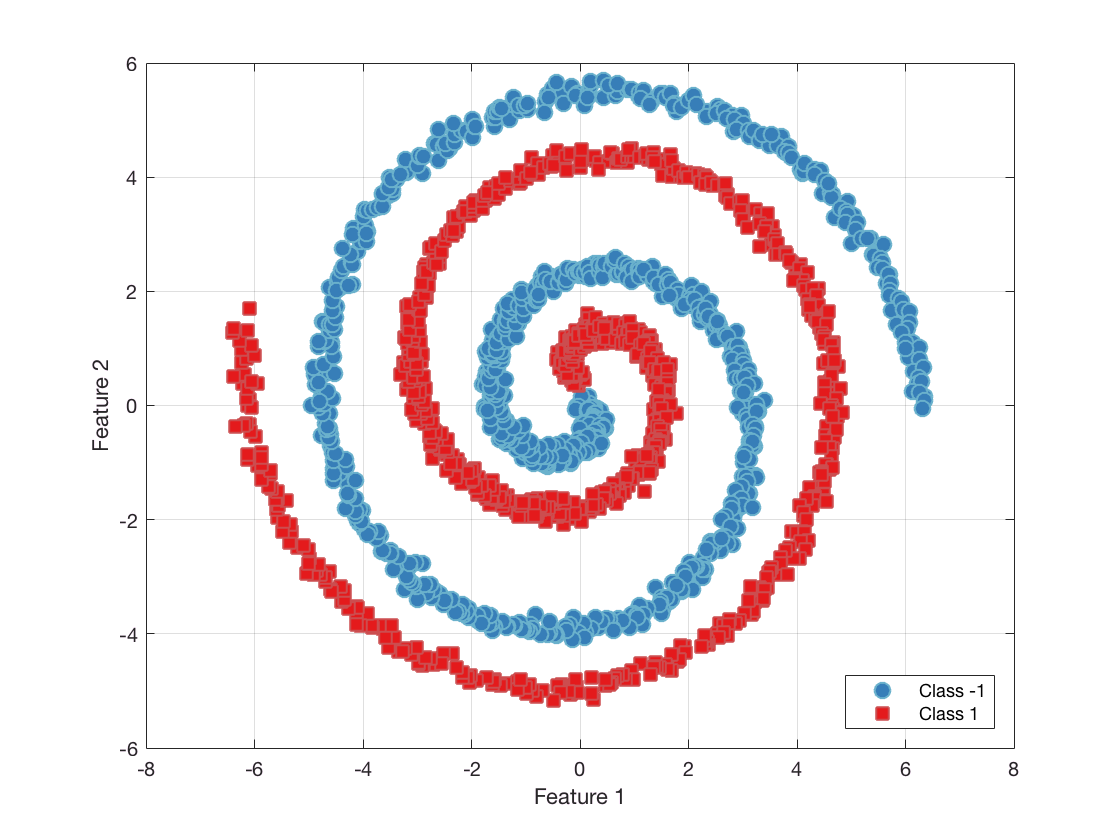

Scheme = 2;
GenParam = '';
data2 = block_data({'Scheme',Scheme,'GenParam',GenParam});
data2.PlotData();

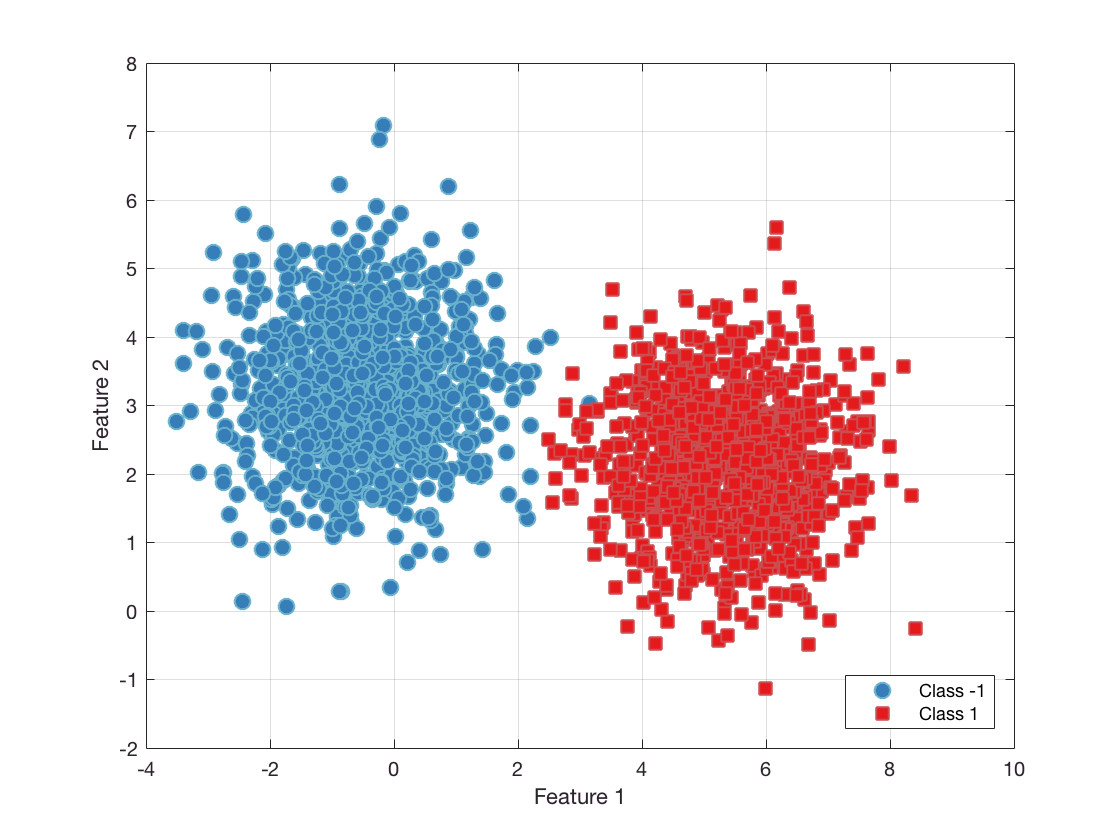

Scheme = 1;
GenParam.Sigma = [eye(2);eye(2)];
GenParam.Mu = [0,0;0,5];
GenParam.nSamples = 1000;
GenParam.nClusters = 2;
GenParam.ClusterLabels = [1,-1];
GenParam.Noise = 2; 
data3 = block_data({'Scheme',Scheme,'GenParam',GenParam});
data3.PlotData();

data3.MakeName()

ans = "Gaussianssize1000nclusters2noise2.00labels1-1sigma10011001mu0005"

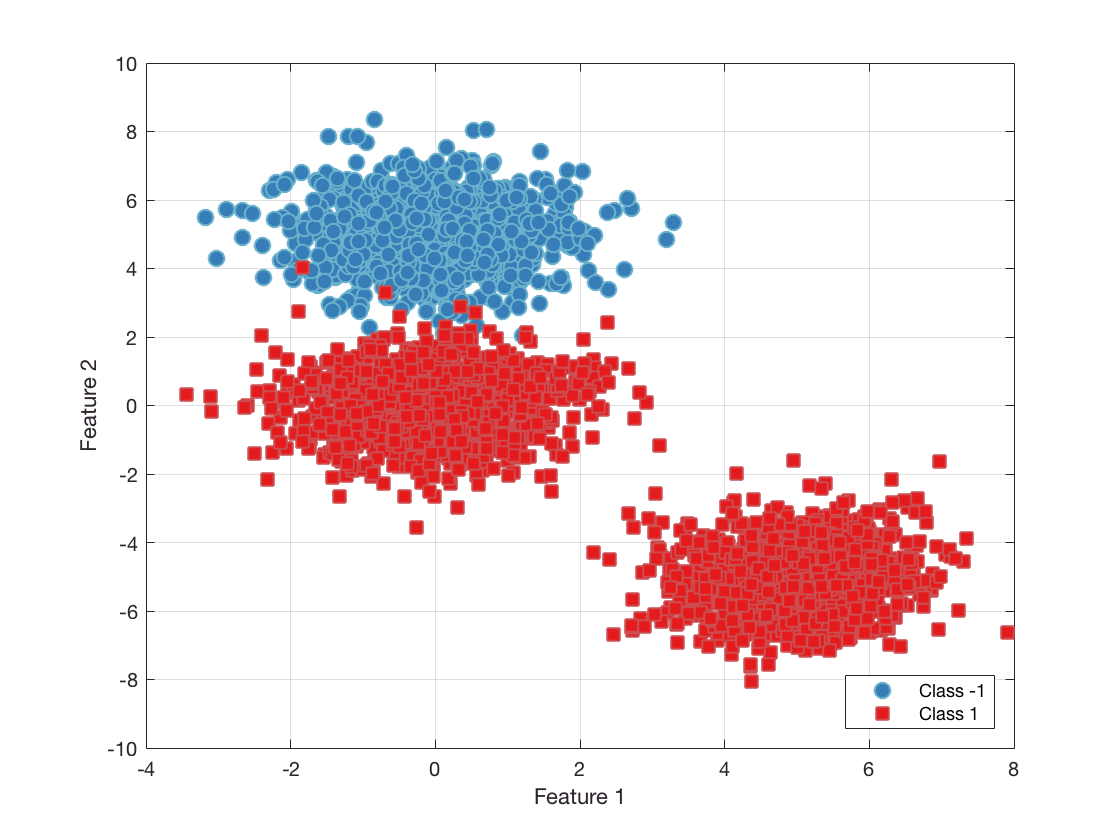

Scheme = 1;
GenParam.Sigma = [eye(2);eye(2);[0.9,0.1;0.1,0.9]];
GenParam.Mu = [0,0;0,5;5,-5];
GenParam.nSamples = 1000;
GenParam.nClusters = 3;
GenParam.ClusterLabels = [1,-1,1];
GenParam.Noise = 0; 
data4 = block_data({'Scheme',Scheme,'GenParam',GenParam});
data4.PlotData();

data4.MakeName()

ans = "Gaussianssize1000nclusters3noise0.00labels1-11sigma100110010.90.10.10.9mu00055-5"

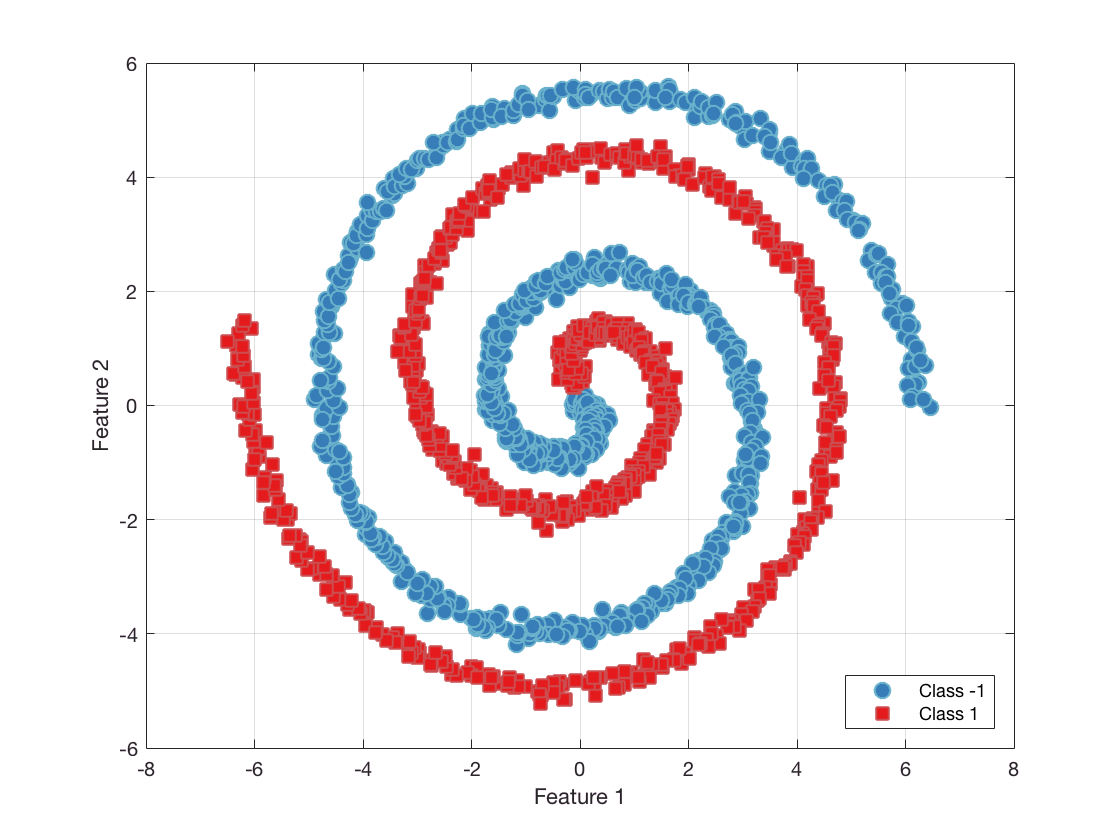

Scheme = 2;
GenParam = '';
data5 = block_data({'Scheme',Scheme,'GenParam',GenParam});
data5.PlotData();

data5.MakeName()

ans = "Spiralssize1000nclusters2noise0.00"

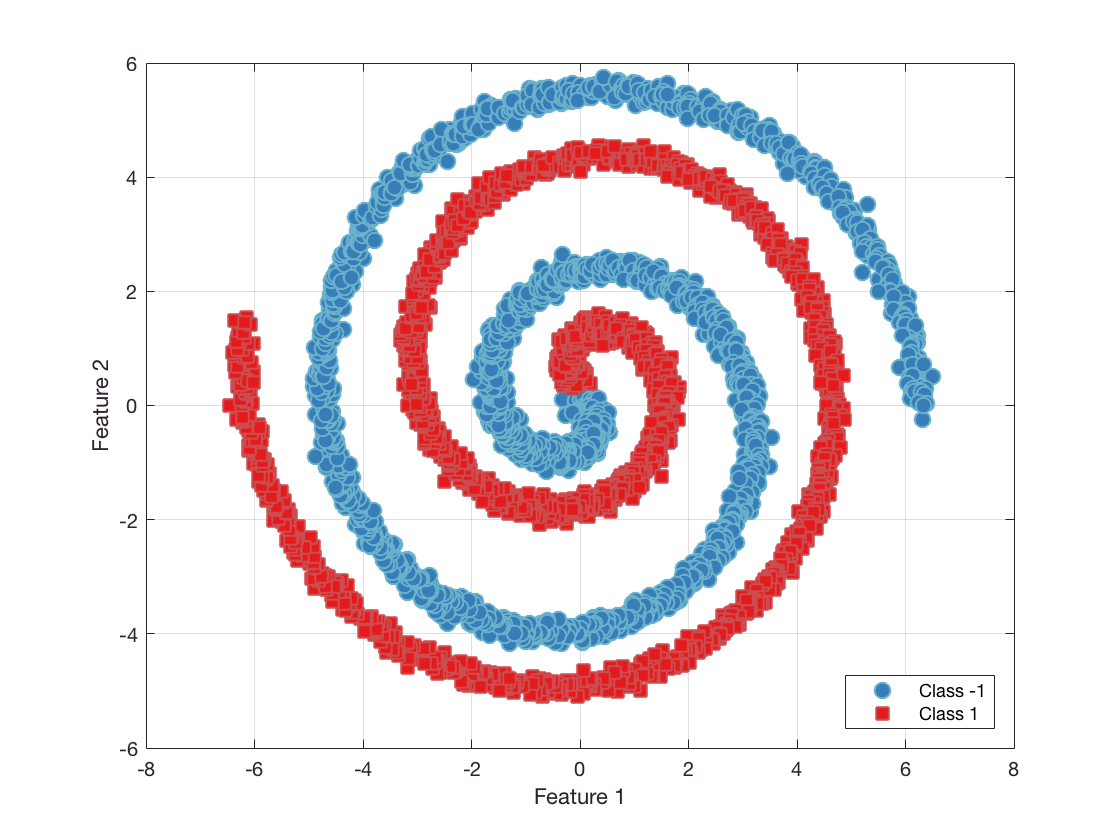

Scheme = 2;
GenParam.nSamples = 3000;
GenParam.nClusters = 2;
GenParam.Noise = 0;
data6 = block_data({'Scheme',Scheme,'GenParam',GenParam});
data6.PlotData();


savedir = '/Users/yueweiyang/Documents/study/duke/independent study/fall 2017/matlab/multiple instance learning/result/data/';
block_data.saveProperties(data6,savedir);

datadir = '/Users/yueweiyang/Documents/study/duke/independent study/fall 2017/matlab/multiple instance learning/result/data/Spiralssize3000nclusters2noise0.00.mat';
data7 = block_data.loadProperties(datadir);
data7.PlotData();

Scheme = 1;
GenParam.Sigma = [eye(2);eye(2)];
GenParam.Mu = [0,0;0,5];
GenParam.nSamples = 1000;
GenParam.nClusters = 2;
GenParam.ClusterLabels = [1,-1];
GenParam.Noise = 2; 
data3 = block_data({'Scheme',Scheme,'GenParam',GenParam});
data3.PlotData();
data3.MakeName()